clear;close;clc;

## without flare

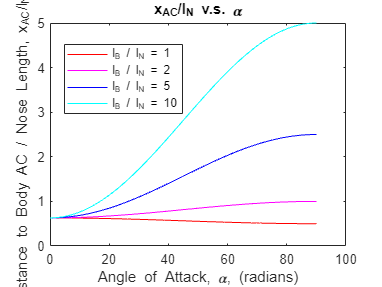

% reproduce fleemans graph for x_AC/l_N v.s. Angle of Attack

% missile geometery
l = [1,2,5,10]; % length of body (m)
l_N = 1; % length of nose (m)


% %scaled nammo
% % for nammo scaled
% d = .105;
% l = [.52,.52,.52,.52];
% l_N = .161;
% d_noseTip = .001;
% d_bt = d;
% A_E = pi * (.073)^2 / 4;



alphas = deg2rad(linspace(0,90,1000));

x_AC_over_l_N = zeros(length(l), length(alphas));

legendString = "l_{B} / l_{N} = %g"; % create the template of legend for the graph
legendStrings = [];

for i = 1:length(l)
    x_AC_over_l_N(i,:) = aerodynamic_Center_Body_Alone(l(i),l_N,alphas) / l_N;
    legendStrings = [legendStrings; sprintf(legendString,l(i))]; % fill out legened template
end


plot1 = plot(rad2deg(alphas),x_AC_over_l_N); xlim([0,100]); ylim([0,5]); legend(legendStrings,Location="best"); ylabel("Distance to Body AC / Nose Length, x_{AC}/l_{N}, (~)", Interpreter="tex"); xlabel("Angle of Attack, \alpha, (radians)"); title("x_{AC}/l_{N} v.s. \alpha");
set(plot1(1), 'Color',"red"); set(plot1(2), 'Color',"magenta"); set(plot1(3), 'Color',"blue"); set(plot1(4), 'Color',"cyan");

## with flare

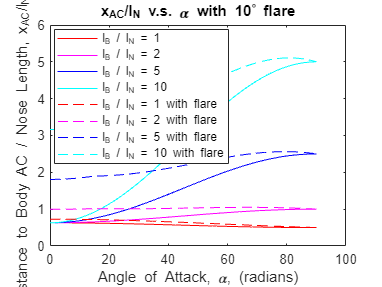

d = 1/10 * l;

l_F = l*.05; % flare is 5% total missile length
flare_Angle = deg2rad(10); % flare angle in radians
d_F = 2*l_F*tan(flare_Angle) + d;
x_F = l - l_F;

for i = 1:length(l)
    for j = 1:length(alphas)
        x_AC_over_l_N(i,j) = aerodynamic_Center_Body(l(i), l_N, l_F(i), d(i)/2, d(i)/2, 0, d_F(i), x_F(i), alphas(j)) / l_N;
    end
        legendStrings = [legendStrings; sprintf(legendString + " with flare",l(i))]; % fill out legened template
end

hold on;
plot1 = plot(rad2deg(alphas),x_AC_over_l_N,"--"); xlim([0,100]); ylim([0,6]); legend(legendStrings,Location="best"); ylabel("Distance to Body AC / Nose Length, x_{AC}/l_{N}, (~)", Interpreter="tex"); xlabel("Angle of Attack, \alpha, (radians)"); title("x_{AC}/l_{N} v.s. \alpha with 10^\circ flare");
set(plot1(1), 'Color',"red"); set(plot1(2), 'Color',"magenta"); set(plot1(3), 'Color',"blue"); set(plot1(4), 'Color',"cyan");